Three Circles

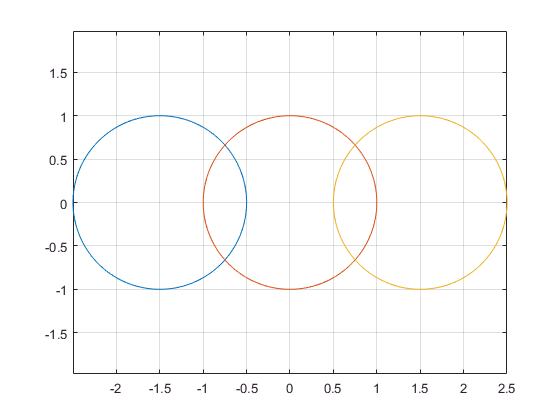

N = 1000;
t = linspace(0,2*pi, N);
x = cos(t); y = sin(t);
figure(1);
plot( x-1.5, y, x, y, x+1.5, y );
axis equal; grid on;

Center Intersection

N2 = 100; 
t0 = atan2( sqrt(7), 3 );
t1 = linspace(-t0, t0, N2 );
t2 = linspace( t0, pi - t0, N2 );
x1 = cos(t1); y1 = sin(t1);
x2 = cos(t2), y2 = sin(t2);

x2 =     0.7500    0.7386    0.7269    0.7150    0.7029    0.6907    0.6782    0.6655    0.6526    0.6395    0.6263    0.6128    0.5992    0.5854    0.5714    0.5573    0.5429    0.5285    0.5139    0.4991    0.4842    0.4691    0.4539    0.4386    0.4231    0.4075    0.3918    0.3760    0.3601    0.3440    0.3279    0.3117    0.2953    0.2789    0.2624    0.2459    0.2292    0.2125    0.1958    0.1789    0.1620    0.1451    0.1281    0.1111    0.0941    0.0770    0.0599    0.0428    0.0257    0.0086


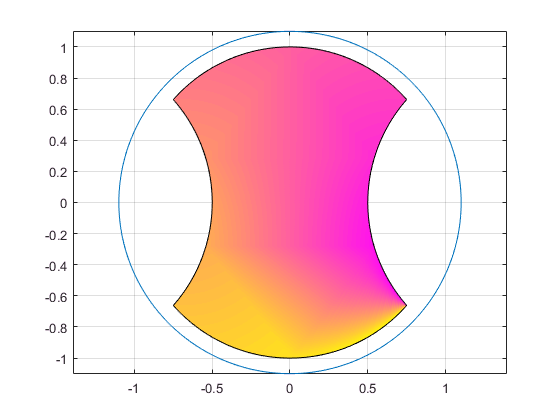

xc = [1.5-x1, x2, -1.5+x1, -x2];
yc = [y1, y2, -y1, -y2];
cc = (0:length(xc)-1)/15;
figure(2);
plot( 1.1*x, 1.1*y ); hold on;
patch( xc, yc, cc );
colormap('spring');
axis equal; grid on;
hold off;

Rotating Intersection

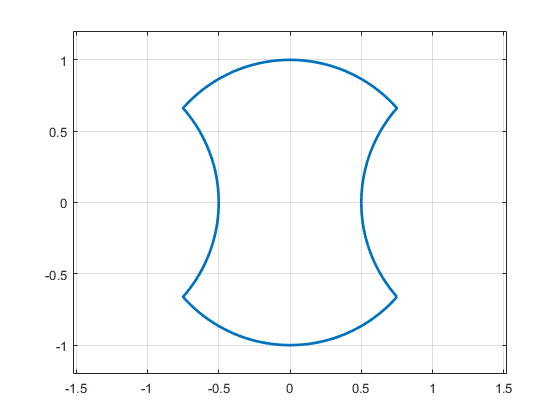

figure(3);

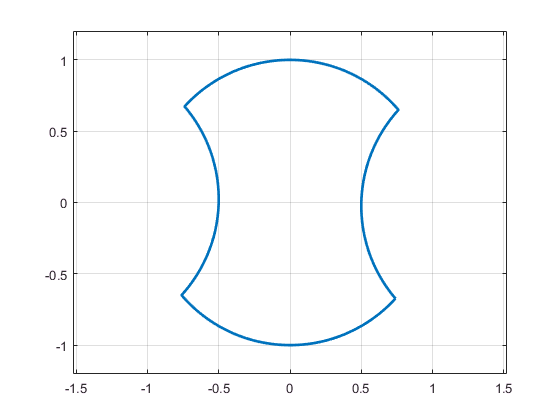

plot( 1.1*x, 1.1*y ); hold on;
h = patch( xc, yc, cc );
axis([-1 1 -1 1]*1.2); axis equal; grid on;
colormap('spring');
for t = 0:0.1:10*pi
    c = cos(t); s = sin(t);
    R = [c -s; s c ];
    P = R * [xc; yc];
    h.XData = P(1,:);
    h.YData = P(2,:);
    refresh;
    pause(0.05);
end